clc;close all;clear;
syms alpha1 
eqns=cos(0.2*pi)==2*alpha1/(1+alpha1^2);
alpha1=solve(eqns,alpha1);
res=double(alpha1(1));
res=roundn(res,-4)

res = 0.5095

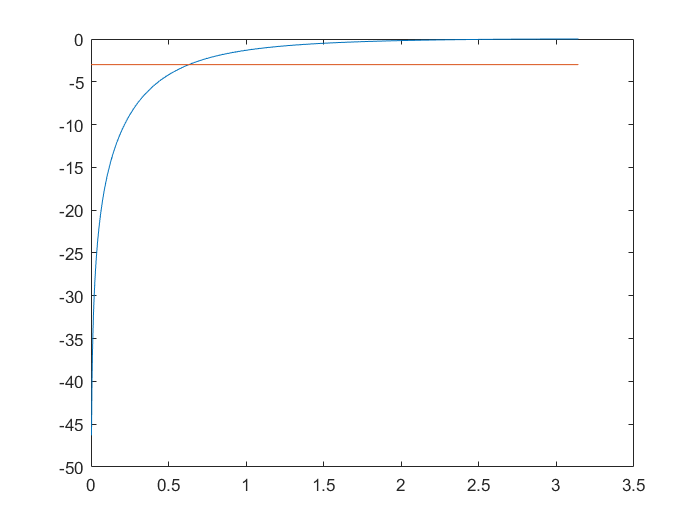

w=linspace(0,pi,1000);
H=sqrt(((1+res)^2.*(1-cos(w)))./(2.*(1+res.^2-2.*res.*cos(w))));
figure(1);
plot(w,20*log10(abs(H)));
hold on;
plot(w,-3*ones(1,1000));